# Actividad 1: Velocidades lineales y angulares 

Ana Itzel Hernández García 

**Obtener** el vector de velocidades lineal y angular para la siguiente configuración:

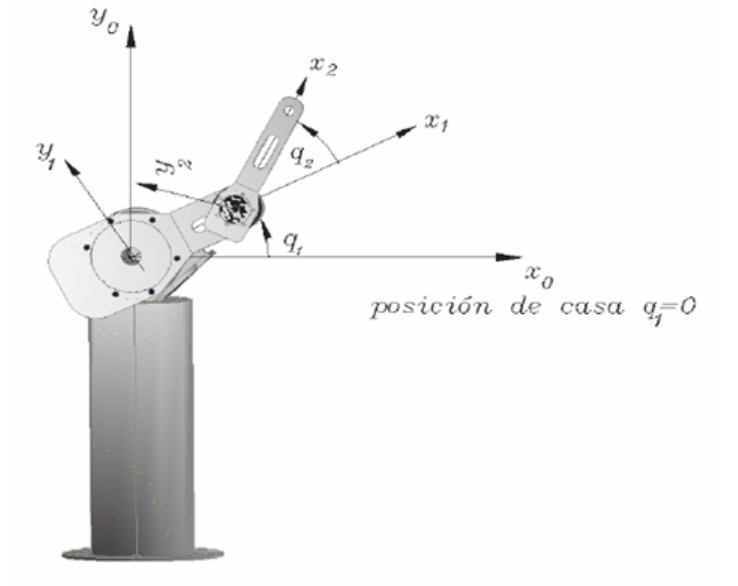

Limpieza de pantalla/ entorno

clear all
close all
clc

### **Declaración de variables**

syms th1(t) l1
syms th2(t) l2

Configuración del robot (**0** para junta **rotacional**, 1 para junta prismatica)

RP=[0 0];

Creamos el vector de coordenadas generalizadas

Q = [th1 th2];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


Q

$$Q(t) = \left(\begin{array}{cc} {\mathrm{th}}_{1}\left(t\right) & {\mathrm{th}}_{2}\left(t\right) \end{array}\right)$$

Creamos el vector de velocidades generalizadas

Qp = diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


Qp

$$Qp(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right) \end{array}\right)$$

Grados de libertad del robot

GDL = size(RP,2); 
GDL_str = num2str(GDL);

### Articulación 1 

Posición de la junta 1 respecto a 0

P(:,:,1) = [l1*cos(th1);
            l1*sin(th1); %Vector de posición indexado por página
            0];

Matriz de rotación de la junta 1 respecto a 0

R(:,:,1) = [cos(th1) -sin(th1) 0;
            sin(th1)  cos(th1) 0; %Análisis del robot pendulo
               0         0     1];

### Articulación 2 

Posición de la junta 2 respecto a 0

P(:,:,2) = [l2*cos(th2);
            l2*sin(th2); %Vector de posición indexado por página
            0];

Matriz de rotación de la junta 1 respecto a 0

R(:,:,2) = [cos(th2) -sin(th2) 0;
            sin(th2)  cos(th2) 0; %Análisis del robot pendulo
               0         0     1];

### Matrices

%Creamos un vector de ceros 
Vector_Zeros = zeros(1,3);

Inicializamos las matrices de transformaciones homogéneas locales

A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Inicializamos las matrices de transformaciones homogéneas globales

T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Inicializamos los vectoresde posición vistos desde el marco de referencia inical

PO(:,:,GDL) = P(:,:,GDL);

Inicializamos los matrices de rotación vistos desde el marco de referencia inical

RO(:,:,GDL) = R(:,:,GDL);

for i = 1: GDL
    i_str = num2str(i);

    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    A(:,:,i)

    %Globales
    try 
        T(:,:,i) = T(:,:,i-1) * A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i);  %Cao especifico cuando i=1
    end
    disp(strcat('Matriz de transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i));
    T(:,:,i)

    %Obtenemos lamatriz derotación "RO" y el vector de traslación PO de la 
    %Matriz de transformación homogenéa blobal 
    RO(:,:,i) = T(1:3, 1:3, i);
    PO(:,:,i) = T(1:3, 4, i);

    RO(:,:,i)
    PO(:,:,i)
end

Matriz de Transformación local A1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de transformación global T1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$ans = \left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

Matriz de Transformación local A2


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de transformación global T2


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

$$ans = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$ans = \left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 \end{array}\right)$$

### Calculamos el jacobiano lineal de forma diferencial

disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial



%Matriz de transformación homogénea total
c = [0;0;0];

Vector auxiliar para completar la matriz de transformación

H1 = [R(:,:,1) P(:,:,1); c' 1]; % Matriz de transformaciónde la base a la primera junta
H2 = [R(:,:,2) P(:,:,2); c' 1]; % Matriz de transformaciónde la primera a la segunda junta
MG = H1 * H2; % Matriz de transformación homogénea total

Coordenadas Finales

x = MG(1,4);
y = MG(2,4);
z = MG(3,4);

#### Derivadas parciales 

%Derivadas parciales de x respecto a th1
Jv11 = functionalDerivative(x,th1);

%Derivadas parciales de y respecto a th1
Jv21 = functionalDerivative(y,th1);

%Derivadas parciales de z respecto a th1
Jv31 = functionalDerivative(z,th1);

%Derivadas parciales de x respecto a th2
Jv12 = functionalDerivative(x,th2);

%Derivadas parciales de y respecto a th1
Jv22 = functionalDerivative(y,th2);

%Derivadas parciales de z respecto a th1
Jv32 = functionalDerivative(z,th2);

disp('Cinemática diferencial de la posición del péndulo');

Cinemática diferencial de la posición del péndulo


Obtenemos la cinématica diferencial del péndulo a partir de la cinématica directa

jv_d = simplify([Jv11 Jv12; 
                Jv21 Jv22; 
                Jv31 Jv32]);
jv_d

$$jv\_d(t) = \left(\begin{array}{cc} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)-l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

### Calculamos el jacobiano lineal y angular de forma analítica

Inicializamos jacobianos analíticos 

Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL); %Angular

for k = 1:GDL
    if ((RP(k)==0) | (RP(k)==1)) %Casos: articulación rotacional y prismatica

        %Para articulaciones rotacionales
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:, GDL)- PO(:,:, k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0,0,1], PO(:,:,GDL)); %Matriz de rotación de 0 con respecto a 0 es la matriz identidad, la posición previa tambien sera 0
            Jw_a(:,k) = [0 ,0, 1]; %Si no hay matriz de rotación previa se obtiene la matrizde identidad
        end

    elseif (RP(K) == 1) %Casos: articulaciones prismáticas
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0, 0, 1]; %Si no hay matriz de rotación previa se obtiene de la matriz identidad
        end
            Jw_a(:,k) = [0, 0, 0];
    end
end

### Despliegue

Jv_a = simplify(Jv_a);
Jw_a = simplify(Jw_a);
disp('Jacobiano lineal obtenido de forma analitica');

Jacobiano lineal obtenido de forma analitica


Jv_a

$$Jv\_a = \left(\begin{array}{cc} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)-l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

disp('Jacobiano ángular obtenido de forma analitica');

Jacobiano ángular obtenido de forma analitica


Jw_a

$$Jw\_a = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$


disp('Velocidad líneal obtenida mediante el Jacobiano líneal');

Velocidad líneal obtenida mediante el Jacobiano líneal


V = simplify(Jv_a*Qp');
V

$$V(t) = \begin{array}{l} \left(\begin{array}{c} -\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\left(l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{1}\right)-l_{2}\,\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\,\sigma_{1}\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\left(l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{2}\right)+l_{2}\,\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\,\sigma_{2}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W = simplify(Jw_a*Qp');
W

$$W(t) = \left(\begin{array}{c} 0\\ 0\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)} \end{array}\right)$$